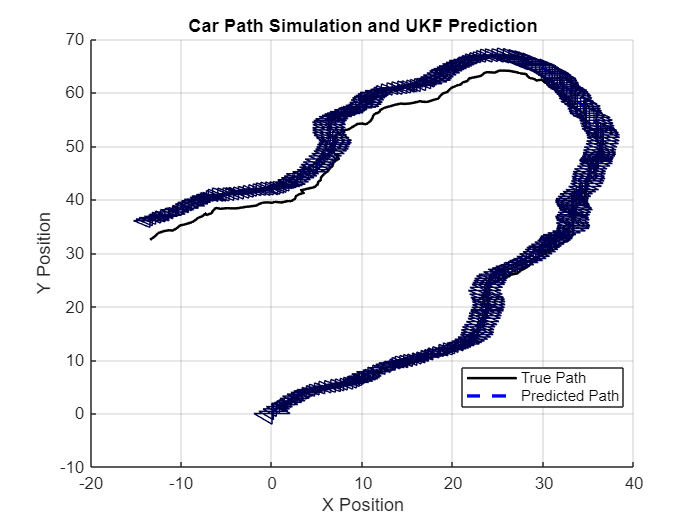

% Simulation parameters
dt = 0.1; % Time step (seconds)
T = 30; % Total time (seconds)
N = T / dt; % Number of time steps

% Car's true path (jagged)
true_path = zeros(N, 2); % [x, y] positions
true_velocity = 5; % constant speed
true_direction = pi/4; % initial direction (45 degrees)
noise_level = 0.2; % noise level for jaggedness

% Generate a jagged path
for i = 2:N
    true_direction = true_direction + randn * 0.1; % Jagged direction change
    true_velocity = true_velocity + randn * 0.1; % Jagged velocity change
    true_path(i, 1) = true_path(i-1, 1) + true_velocity * cos(true_direction) * dt;
    true_path(i, 2) = true_path(i-1, 2) + true_velocity * sin(true_direction) * dt;
    % Add some noise to make the path jagged
    true_path(i, 1) = true_path(i, 1) + randn * noise_level;
    true_path(i, 2) = true_path(i, 2) + randn * noise_level;
end

% UKF initialization
x = [true_path(1, 1); true_path(1, 2); 0; 0]; % initial state [x, y, vx, vy]
P = eye(4) * 1; % initial covariance
Q = diag([0.1, 0.1, 0.1, 0.1]); % process noise covariance
R = diag([0.5, 0.5]); % measurement noise covariance

% State transition function
f = @(x, dt) [
    x(1) + x(3) * dt;
    x(2) + x(4) * dt;
    x(3);
    x(4)
];

% Measurement function (direct observation of position)
h = @(x) [x(1); x(2)];

% UKF filtering
predicted_path = zeros(N, 2);
predicted_path(1, :) = x(1:2)'; % initial predicted state

% Create figure
figure;
hold on;

% Plot the true path (green)
h_true = plot(true_path(:, 1), true_path(:, 2), 'k-', 'LineWidth', 1.5); 

% Plot the predicted path (blue dashed)
h_predicted = plot(predicted_path(:, 1), predicted_path(:, 2), 'b--', 'LineWidth', 2);

% Set up the sigma points' color
sigma_color = [0, 0, 0.3, 0.3]; % translucent blue (RGBA)

% Loop for UKF prediction and update
for t = 2:N
    % Propagate the state using the Unscented Kalman Filter approach
    [x, P, sigma_points] = ukf_predict(f, x, P, Q, dt);
    [x, P, sigma_points] = ukf_update(h, x, P, R, true_path(t, :)', sigma_points);

    % Plot the sigma points
    plot(sigma_points(1, :), sigma_points(2, :), '-', 'Color', sigma_color);

    % Store the predicted path
    predicted_path(t, :) = x(1:2)';
end

% Update the predicted path plot
set(h_predicted, 'XData', predicted_path(:, 1), 'YData', predicted_path(:, 2));

% Add legend
legend([h_true, h_predicted], {'True Path', 'Predicted Path'}, 'Location', 'Best');
title('Car Path Simulation and UKF Prediction');
xlabel('X Position');
ylabel('Y Position');
grid on;


% Functions for UKF prediction and update
function [x, P, sigma_points] = ukf_predict(f, x, P, Q, dt)
    % Unscented Kalman Filter prediction step
    n = length(x);
    alpha = 1e-3;
    beta = 2;
    kappa = 0;

    lambda = alpha^2 * (n + kappa) - n;
    gamma = sqrt(n + lambda);
    
    % Generate sigma points
    sigma_points = sigmaPoints(x, P, gamma);
    
    % Predict sigma points and calculate predicted mean and covariance
    predicted_sigma_points = zeros(n, 2*n);
    for i = 1:2*n
        predicted_sigma_points(:, i) = f(sigma_points(:, i), dt);
    end
    
    x_pred = mean(predicted_sigma_points, 2);
    P_pred = cov(predicted_sigma_points') + Q;
    
    x = x_pred;
    P = P_pred;
end

function [x, P, sigma_points] = ukf_update(h, x, P, R, z, sigma_points)
    % Unscented Kalman Filter update step
    n = length(x);
    alpha = 1e-3;
    beta = 2;
    kappa = 0;

    lambda = alpha^2 * (n + kappa) - n;
    gamma = sqrt(n + lambda);
    
    % Predict measurements for each sigma point
    predicted_measurements = zeros(2, 2*n);
    for i = 1:2*n
        predicted_measurements(:, i) = h(sigma_points(:, i));
    end
    
    z_pred = mean(predicted_measurements, 2);
    P_zz = cov(predicted_measurements') + R;
    P_xz = zeros(n, 2); % Initialize P_xz matrix

    % Calculate the cross-covariance P_xz
    for i = 1:2*n
        P_xz = P_xz + (sigma_points(:, i) - x) * (predicted_measurements(:, i) - z_pred)';
    end
    P_xz = P_xz / (2*n); % Normalize by the number of sigma points

    % Compute Kalman gain and update state
    K = P_xz / P_zz;
    x = x + K * (z - z_pred);
    P = P - K * P_zz * K';
end

function sigma_points = sigmaPoints(x, P, gamma)
    % Compute sigma points for the Unscented Kalman Filter
    n = length(x);
    sigma_points = zeros(n, 2*n);
    sigma_points(:, 1) = x;
    
    A = chol((n + gamma) * P)';
    for i = 1:n
        sigma_points(:, i+1) = x + A(:, i);
        sigma_points(:, n+i+1) = x - A(:, i);
    end
end
